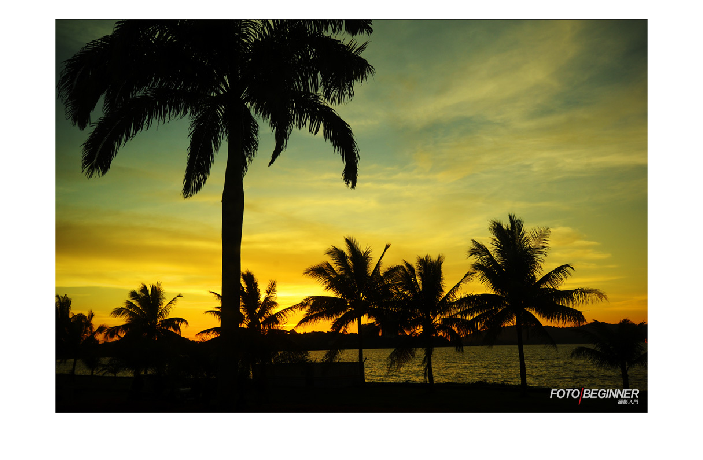

clear all;
clf;
sky=imread('Q1\sky.jpg');
imshow(sky);

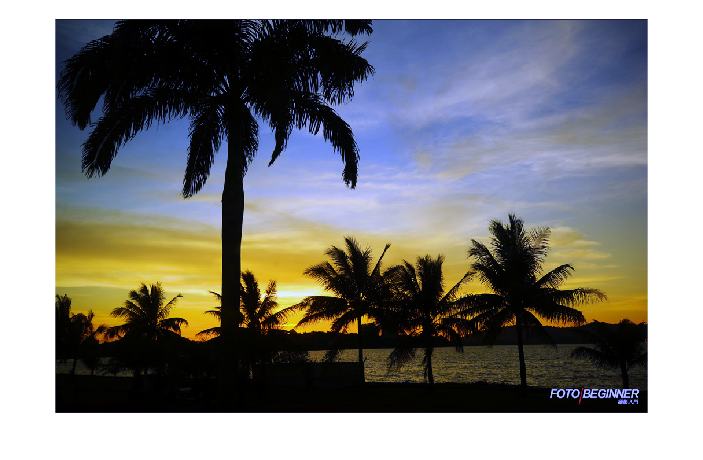

fr=sky(:,:,1);
fg=sky(:,:,2);
fb=sky(:,:,3);
i=0.299*fr+0.587*fg+0.114*fb;
imean=sum(i(:));
frmean=sum(fr(:));fgmean=sum(fg(:));fbmean=sum(fb(:));
kr=imean/frmean;kg=imean/fgmean;kb=imean/fbmean;
gr=kr*fr;gg=kg*fg;gb=kb*fb;
whitebalance=cat(3,gr,gg,gb);
imshow(whitebalance);